作业2

1、`请仿真实现一种灰度变换增强图像`

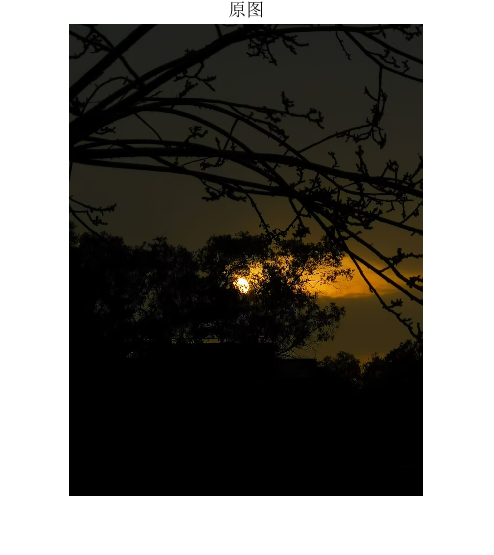

clear;clc;
img_gray=imread('hwk2.jpg');
[m,n]=size(img_gray);
figure(1);
imshow(uint8(img_gray));
title('原图');

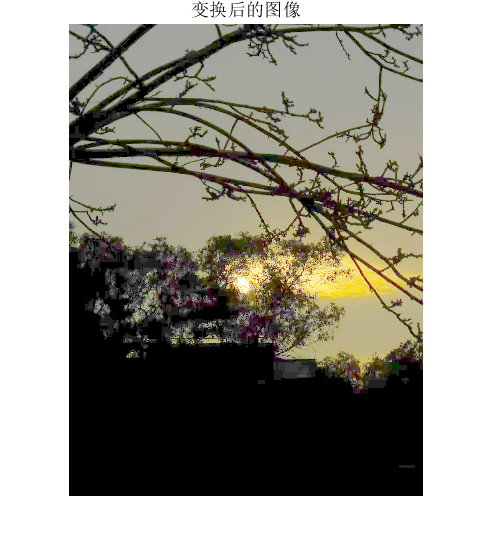

%采用log2增强
img_change=32*log2(1+double(img_gray));
figure(2);
imshow(uint8(img_change));
title('变换后的图像');

实验结论：

实验中采用了对数变化进行增强，所使用的公式如下：

                                           
$$s\ =\ T\left\lbrack r\right\rbrack \ =\ 32*{log}_2 \left(1\ +\ r\right)$$


其对应的图像如下所示：

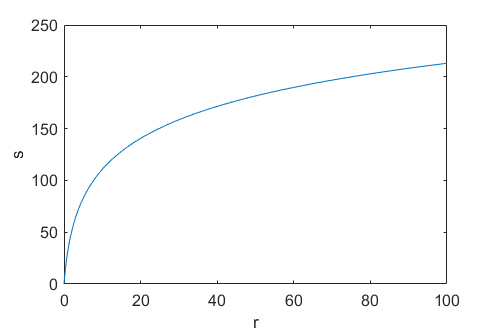

clc;clear;
x = 0:0.1:100;
y = 32*log2(1+x);
figure(1)
plot(x,y)
xlabel("r");ylabel("s")

`    从函数图像可以看出，变换函数对低灰度范围的数值进行扩展，而对高灰度范围的数值进行压缩。对比实验结果可以看出，原来由于黑暗环境下看不见花的颜色，而在经过变换之后整体亮度变亮，可以看到粉色的花。`

2、仿真实现一副图像的直方图

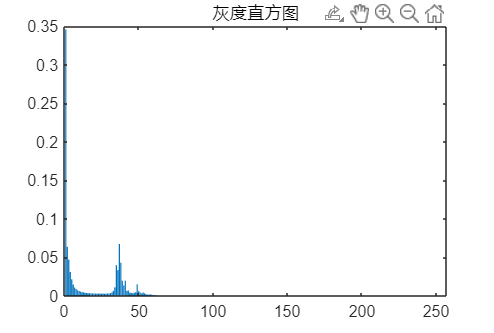

clc;clear;
img=imread("hwk2.jpg");
img_gray=rgb2gray(img);
[m,n]=size(img_gray);
N = 256;
hit = zeros(1,N);
for a =1:N
    %对逻辑数组进行求和
    hit(a)=sum(img_gray==a-1,"all");
end
hit=hit/(m*n);
bar(1:N,hit);
title('灰度直方图');

`实验结论：`

`如上图所示为图像的灰度直方图，可以看到图像在灰度值为0附近的频次相较于其他频次更高。`